% --- Valeur par defaut pour que le simulink tourne
alpha = 0;
J_inv = zeros(4, 3);

% -- Global parameters
dt = 1 / 30;
y0 = [2; -141; -6]; % Mesure initiale quand les moteurs sont à 0

% --- Si données depuis simulink
data = out.logsout;
% --- Si préenregistré
%load("jacobian.mat") 

% --- Recuperation des données
u = squeeze(getElement(data, "m_pos").Values.Data);
y = squeeze(getElement(data, "y").Values.Data);
delta_u = diff(u, 1, 2);
delta_y = diff(y, 1, 2);

t  = 1:size(y, 2);
td = 1:size(delta_y, 2);

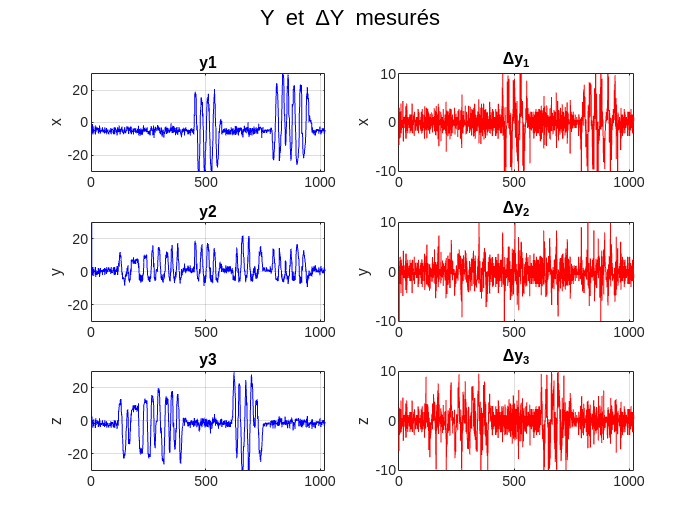

% --- Y et delta_y 
labels_y = {'x', 'y', 'z'};

figure;
for i = 1:3
    subplot(3, 2, 2*i-1);
    plot(t, y(i, :), 'b');
    ylabel(labels_y{i});
    ylim([-30, 30]);
    title(sprintf('y%d', i));
    grid on;

    subplot(3, 2, 2*i);
    plot(td, delta_y(i, :), 'r');
    ylabel(labels_y{i});
    ylim([-10, 10]);
    title(['\Deltay_' num2str(i)], 'Interpreter', 'tex');    
    grid on;
end
sgtitle('Y et \DeltaY mesurés');

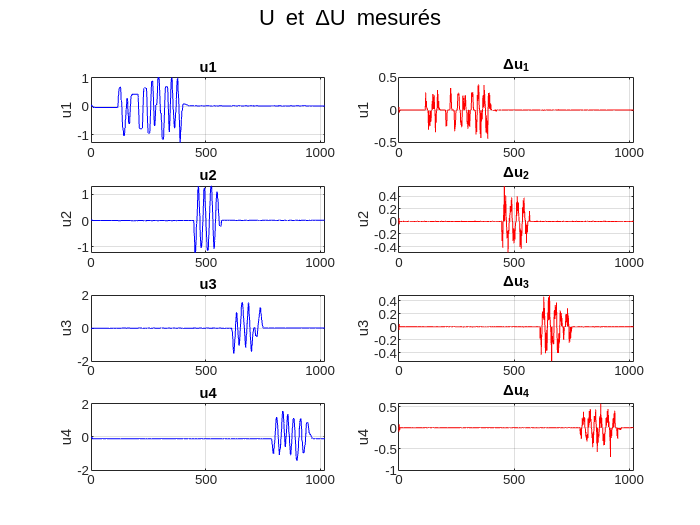

% --- U et delta_u 
labels_u = {'u1', 'u2', 'u3', 'u4'};
figure;
for i = 1:4
    subplot(4, 2, 2*i-1);
    plot(t, u(i, :), 'b');
    ylabel(labels_u{i});
    title(sprintf('u%d', i));
    grid on;

    subplot(4, 2, 2*i);
    plot(td, delta_u(i, :), 'r');
    ylabel(labels_u{i});
    title(['\Deltau_' num2str(i)], 'Interpreter', 'tex');    
    grid on;
end
sgtitle('U et \DeltaU mesurés');

% --- Traitement et calul de la jacobienne
seuil = 0.01;  % rad
mask = any(abs(delta_u) > seuil, 1);

delta_u_filtered = delta_u(:, mask);
delta_y_filtered = delta_y(:, mask);

J = delta_y_filtered * pinv(delta_u_filtered);
J_inv = pinv(J);

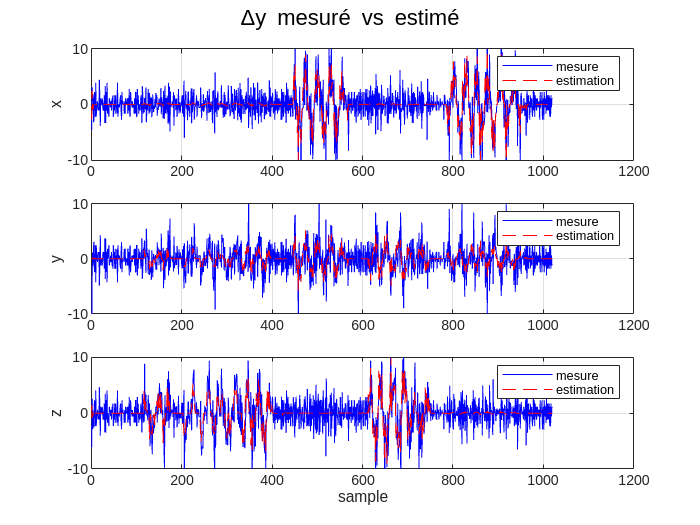

% ---Verification
delta_y_est = J * delta_u;
labels = {'x', 'y', 'z'};
figure;
for i = 1:3
    subplot(3, 1, i);
    plot(td, delta_y(i, :), 'b', 'DisplayName', 'mesure');
    hold on;
    plot(td, delta_y_est(i, :), 'r--', 'DisplayName', 'estimation');
    ylabel(labels{i});
    ylim([-10, 10]);
    legend;
    grid on;
end
xlabel('sample');
sgtitle('\Deltay mesuré vs estimé');

% --- Closed Loop parameter
alpha = 5e-2;